%% C.1.a

% Load the provided .mat files for Oblong TPU and Oblong Rubber objects
oblong_peak_TPU = load('/Users/tamamabibi/Downloads/oblong_TPU_peak_data.mat');
oblong_rubber = load('/Users/tamamabibi/Downloads/oblong_rubber_peak_data.mat');

oblong_TPU_displacement = oblong_peak_TPU.peak_tactile_displacement;
oblong_rubber_displacement = oblong_rubber.peak_tactile_displacement;

% Extract the central papillae displacement (P4, index 4)
oblong_TPU_P4 = oblong_TPU_displacement(:, 10:12); % Columns 10-12 for P4 (X, Y, Z)
oblong_rubber_P4 = oblong_rubber_displacement(:, 10:12); % Columns 10-12 for P4

% Combine data and create labels
X = [oblong_TPU_P4; oblong_rubber_P4];
y = [ones(size(oblong_TPU_P4, 1), 1); 2 * ones(size(oblong_rubber_P4, 1), 1)];

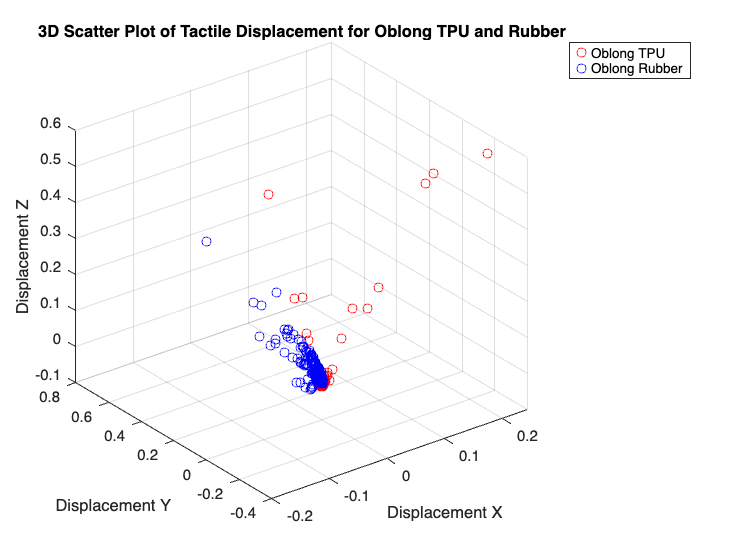

%% C.1.b Visualise the tactile displacement with a 3D scatter plot
figure;
scatter3(oblong_TPU_P4(:, 1), oblong_TPU_P4(:, 2), oblong_TPU_P4(:, 3), 'r', 'DisplayName', 'Oblong TPU');
hold on;
scatter3(oblong_rubber_P4(:, 1), oblong_rubber_P4(:, 2), oblong_rubber_P4(:, 3), 'b', 'DisplayName', 'Oblong Rubber');
grid on;
xlabel('Displacement X'); ylabel('Displacement Y'); zlabel('Displacement Z');
legend;
title('3D Scatter Plot of Tactile Displacement for Oblong TPU and Rubber');

Observations of the 3D plot

**Class separation:**

Oblong TPU - more spread out along the positive z-axis and both positive/negative Y-axis.

Oblong rubber - more Compact and closed in

**Range of Displacement**:

The TPU (red) displays a larger range in the Z-axis and Y-axis compared to the Rubber (blue), indicating that the TPU material exhibits a broader displacement spectrum.

The Rubber (blue) has a more compact distribution in 3D space.

**Directionality**:

The TPU seems to have a directional bias in its displacement pattern, with displacements extending more along certain axes.

The Rubber displacement points are concentrated around a smaller region, implying less variation and perhaps higher stiffness or resistance to deformation.

**Material Behavior**:

The spread and clustering differences likely reflect material properties such as flexibility, elasticity, or resistance to deformation under tactile forces.

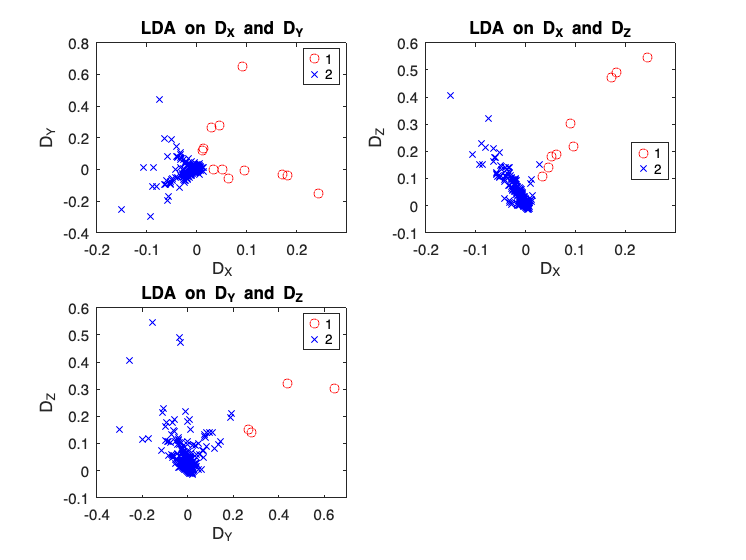

%% C.1.c Apply LDA to 2D combinations of D_X, D_Y, and D_Z
combinations = nchoosek(1:3, 2); % All 2D combinations of [X, Y, Z]
figure;
for i = 1:size(combinations, 1)
    subplot(2, 2, i);
    lda_model = fitcdiscr(X(:, combinations(i, :)), y);
    lda_predictions = predict(lda_model, X(:, combinations(i, :)));
    
    gscatter(X(:, combinations(i, 1)), X(:, combinations(i, 2)), lda_predictions, 'rb', 'ox');
    xlabel(['D_' char('X' + combinations(i, 1) - 1)]);
    ylabel(['D_' char('X' + combinations(i, 2) - 1)]);
    title(['LDA on ', ['D_' char('X' + combinations(i, 1) - 1)], ' and ', ['D_' char('X' + combinations(i, 2) - 1)]]);
end

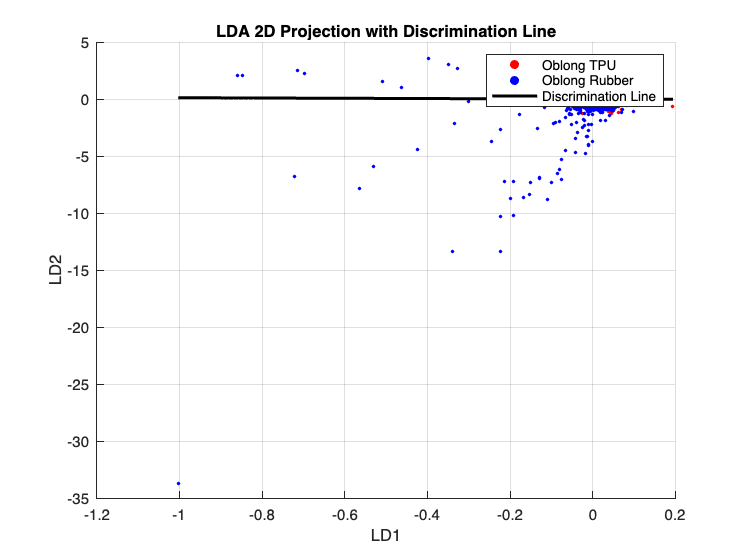

%% C.1.d - Reduce to 2D and replot

% Reducing the data to 2 Dimensions and Re-plot

% Combine all displacement data for TPU and Rubber
displacement_data = [oblong_TPU_displacement; oblong_rubber_displacement];

% Create class labels (0 = TPU, 1 = Rubber)
labels = [zeros(size(oblong_TPU_displacement, 1), 1); ones(size(oblong_rubber_displacement, 1), 1)];

% Apply LDA
lda_model = fitcdiscr(displacement_data, labels);

% Project data into 2D space
lda_2d = lda_model.X .* lda_model.Coeffs(1,2).Linear';

% Extract class-wise projections
lda_tpu = lda_2d(labels == 0, :);
lda_rub = lda_2d(labels == 1, :);

% Plot the 2D LDA result
figure;
scatter(lda_tpu(:,1), lda_tpu(:,2), 5, 'r', 'filled'); % Oblong TPU in red
hold on;
scatter(lda_rub(:,1), lda_rub(:,2), 5, 'b', 'filled'); % Oblong Rubber in blue

% Plot the discrimination line
coeff = lda_model.Coeffs(1,2).Linear;
k = -coeff(1)/coeff(2); % Slope
x_range = linspace(min(lda_2d(:,1)), max(lda_2d(:,1)), 100);
y_range = k * x_range; % Line equation
plot(x_range, y_range, 'k', 'LineWidth', 2); % Black discrimination line

xlabel('LD1');
ylabel('LD2');
title('LDA 2D Projection with Discrimination Line');
legend('Oblong TPU', 'Oblong Rubber', 'Discrimination Line');
grid on;
hold off;

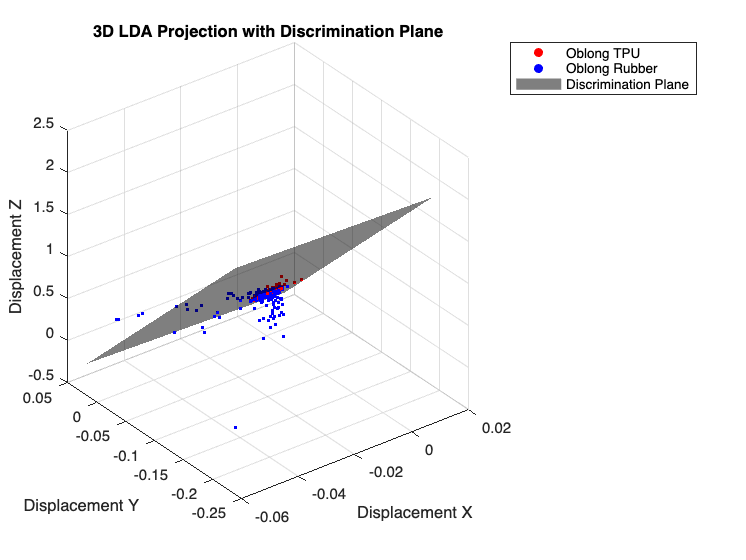

%% C.3.d.i - 3d Plot with plane
% 3D plot with discrimination plane
% Extract 3D displacement data
D_X = displacement_data(:,1);
D_Y = displacement_data(:,2);
D_Z = displacement_data(:,3);

% Plot the 3D displacement points
figure;
scatter3(D_X(labels == 0), D_Y(labels == 0), D_Z(labels == 0), 5, 'r', 'filled'); % TPU
hold on;
scatter3(D_X(labels == 1), D_Y(labels == 1), D_Z(labels == 1), 5, 'b', 'filled'); % Rubber

% Plot the discrimination plane
% Use coefficients of the LDA model
plane_coeff = lda_model.Coeffs(1,2).Linear; % [a, b, c] for ax + by + cz = d
a = plane_coeff(1);
b = plane_coeff(2);
c = plane_coeff(3);
d = lda_model.Coeffs(1,2).Const; % Plane offset

% Define the range for the plane
[x_plane, y_plane] = meshgrid(linspace(min(D_X), max(D_X), 30), linspace(min(D_Y), max(D_Y), 30));
z_plane = -(a*x_plane + b*y_plane + d)/c;

% Plot the plane
surf(x_plane, y_plane, z_plane, 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'FaceColor', 'k');

% Customize the plot
xlabel('Displacement X');
ylabel('Displacement Y');
zlabel('Displacement Z');
title('3D LDA Projection with Discrimination Plane');
legend('Oblong TPU', 'Oblong Rubber', 'Discrimination Plane');
grid on;
hold off;

E) different outcomes

**Observations**

- **3D LDA with Discrimination Plane**:

- The 3D projection highlights the separation between the two classes (Oblong TPU and Oblong Rubber) with a discrimination plane.

- The plane effectively separates the classes in the higher-dimensional space, capturing the significant variance and maximizing class separation.

- **2D LDA Projection**:

- The dimensionality reduction to 2D provides a simplified visualization, projecting the data onto two linear discriminants (LD1 and LD2).

- Class separation is evident, but overlapping regions exist due to some loss of spatial information from the dimensionality reduction.

- **2D LDA with Discrimination Line**:

- The discrimination line clearly distinguishes between the two classes based on their projections onto LD1 and LD2.

- While the line separates the classes, there are areas where the data points are misclassified or lie close to the boundary.

**Physical Properties and Sensor Influence**

- **Oblong TPU vs. Oblong Rubber**:

- **Material Compliance**: TPU is more elastic and flexible than rubber, which could cause greater variations in the tactile displacement measurements. This might lead to more dispersed data points in the feature space.

- **Surface Texture**: Rubber may have a rougher texture compared to TPU, causing a consistent interaction with the sensor, which can result in more tightly clustered points.

- **Force Absorption**: TPU absorbs more force and deforms significantly under pressure, introducing additional nonlinearity to the data compared to rubber.

- These differences likely contribute to the variability in sensor readings, affecting the class separation.

- **Sensor Sensitivity**:

- The tactile sensor's response is likely more sensitive to small deformations caused by TPU, which could result in larger scatter for the TPU class.

- Variations in the mechanical properties of the objects may affect the data density and overlap observed in the 2D projection.